**Load Data**

load("spots_num")

avSpots

avSpots =    80.9250   83.3917   47.6583   47.8000   30.6750   12.2167    9.5667   10.1917   32.4250   47.6000   53.9667   62.8583   85.8500   61.1500   45.1167   36.3500   20.9083   11.4083   37.8250   69.8417  106.0917  100.8000   81.5833   66.4917   34.7750   30.6167    7.0083   19.8167   92.5000  154.3667  125.9250   84.8000   68.0917   38.4583   22.8000   10.1667   24.1000   82.8667  132.0250  130.9083  118.1083   89.8917   66.5833   60.0417   46.9000   41.0000   21.2667   16.0167    6.3917    4.0667


year

year =         1749
        1750
        1751
        1752
        1753
        1754
        1755
        1756
        1757
        1758


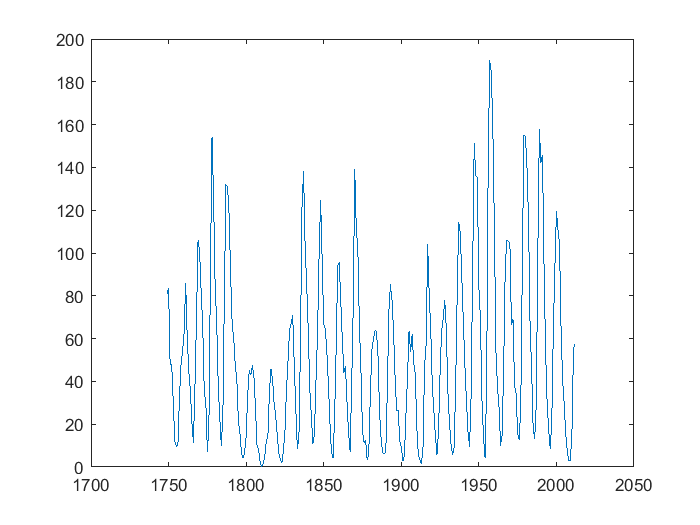

plot(year,avSpots)

To save the figure, first open it in a figure window by clicking on top-right corner of the figure. You can add x/y axis labels, title, etc. using the insert tab. Go to file >> save as to save the image in your pc. Default image format is .fig file. You can save it in any other format such as .png, or .jpg.

**Find Peaks**

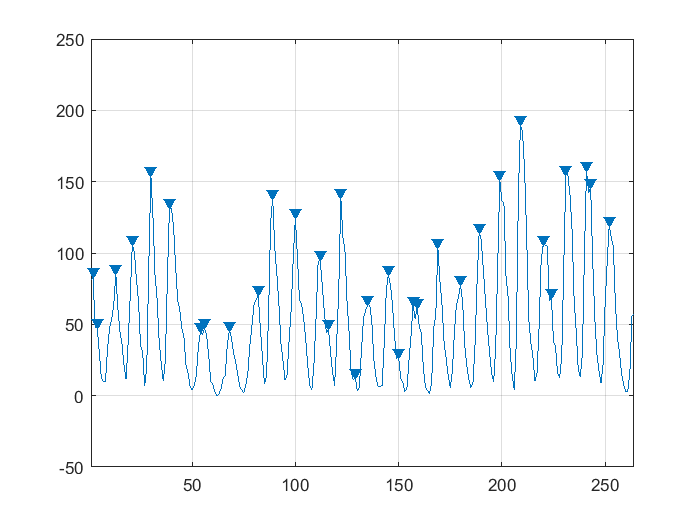

findpeaks(avSpots)

val= findpeaks(avSpots)

val =    83.3917   47.8000   85.8500  106.0917  154.3667  132.0250   45.0333   47.4667   45.8083   70.9417  138.3083  124.7000   95.7917   46.9500  138.9500   12.4083   63.6333   85.0833   26.7167   63.4667   62.0333  103.8917   77.8083  114.4000  151.5083  189.8583  105.8917   68.9333  155.2750  157.7917  145.7750  119.5333


[val,loc] = findpeaks(avSpots)

val =    83.3917   47.8000   85.8500  106.0917  154.3667  132.0250   45.0333   47.4667   45.8083   70.9417  138.3083  124.7000   95.7917   46.9500  138.9500   12.4083   63.6333   85.0833   26.7167   63.4667   62.0333  103.8917   77.8083  114.4000  151.5083  189.8583  105.8917   68.9333  155.2750  157.7917  145.7750  119.5333


loc =      2     4    13    21    30    39    54    56    68    82    89   100   112   116   122   129   135   145   150   157   159   169   180   189   199   209   220   224   231   241   243   252


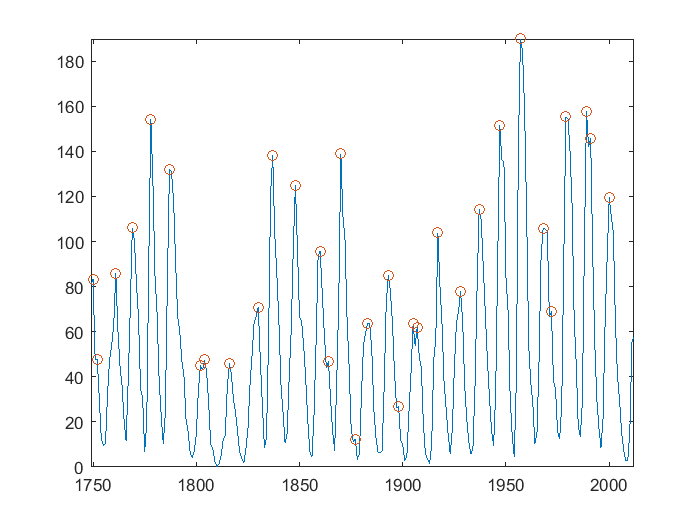

plot(year,avSpots, year(loc), val, "o" )
axis tight

[val2,loc2] = findpeaks(avSpots,"MinPeakDistance",5)

val2 =    83.3917   85.8500  106.0917  154.3667  132.0250   47.4667   45.8083   70.9417  138.3083  124.7000   95.7917  138.9500   12.4083   63.6333   85.0833   63.4667  103.8917   77.8083  114.4000  151.5083  189.8583  105.8917  155.2750  157.7917  119.5333


loc2 =      2    13    21    30    39    56    68    82    89   100   112   122   129   135   145   157   169   180   189   199   209   220   231   241   252


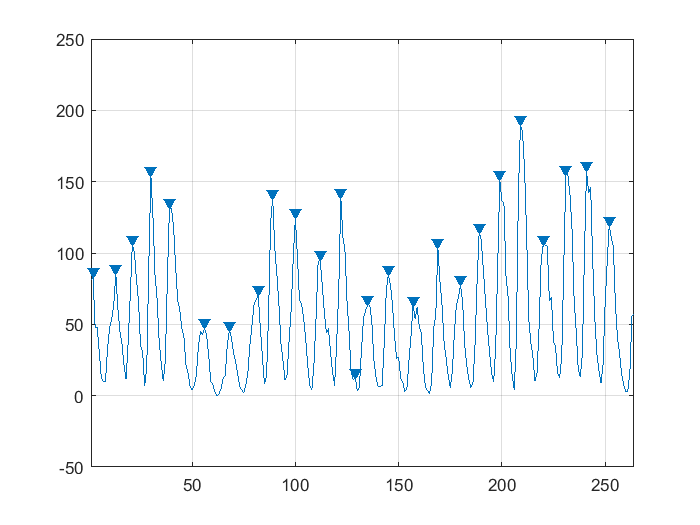

findpeaks(avSpots,"MinPeakDistance",5)

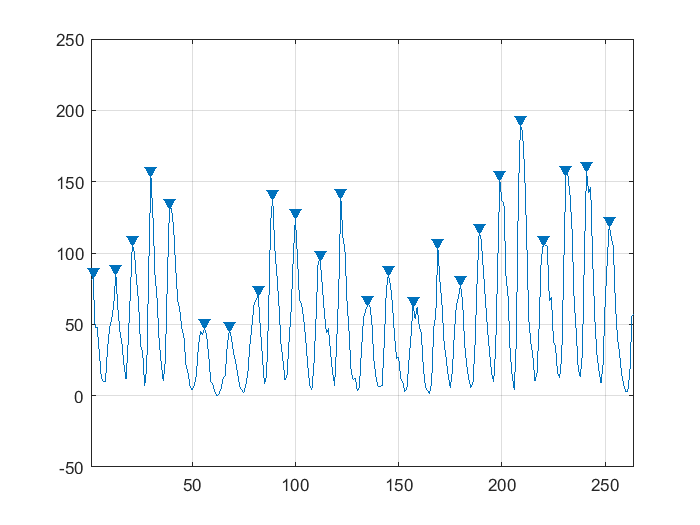

findpeaks(avSpots,"MinPeakDistance", 6)

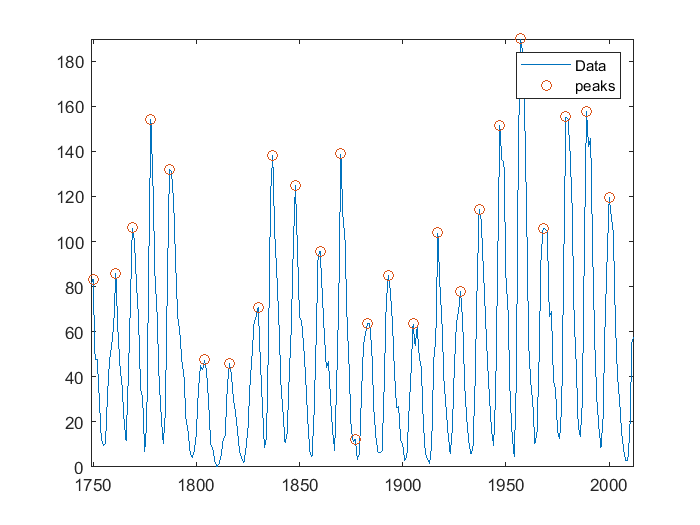

plot(year,avSpots, year(loc2), val2, "o" )
legend(["Data" "peaks"])
axis tight

[val3,loc3] = findpeaks(avSpots,"MinPeakDistance", 6)

val3 =    83.3917   85.8500  106.0917  154.3667  132.0250   47.4667   45.8083   70.9417  138.3083  124.7000   95.7917  138.9500   63.6333   85.0833   63.4667  103.8917   77.8083  114.4000  151.5083  189.8583  105.8917  155.2750  157.7917  119.5333


loc3 =      2    13    21    30    39    56    68    82    89   100   112   122   135   145   157   169   180   189   199   209   220   231   241   252


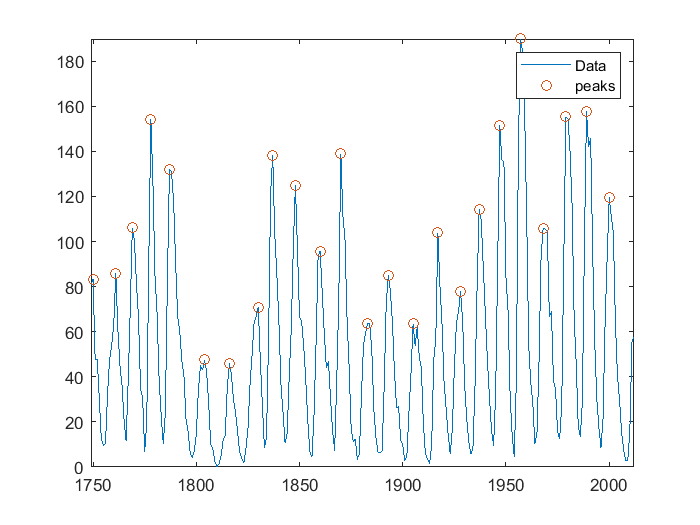

plot(year,avSpots, year(loc3), val3, "o" )
legend(["Data" "peaks"])
axis tight

**Find average interval**

diff(loc3)

ans =     11     8     9     9    17    12    14     7    11    12    10    13    10    12    12    11     9    10    10    11    11    10    11


mean(diff(loc3))

ans = 10.8696

year(loc3)

ans =         1750
        1761
        1769
        1778
        1787
        1804
        1816
        1830
        1837
        1848


val3

val3 =    83.3917   85.8500  106.0917  154.3667  132.0250   47.4667   45.8083   70.9417  138.3083  124.7000   95.7917  138.9500   63.6333   85.0833   63.4667  103.8917   77.8083  114.4000  151.5083  189.8583  105.8917  155.2750  157.7917  119.5333


**Display the output in table**

T= table(year(loc3),val3')

T = 24×2 table
    Var1     Var2 
    ____    ______

    1750    83.392
    1761     85.85
    1769    106.09
    1778    154.37
    1787    132.03
    1804    47.467
    1816    45.808
    1830    70.942
    1837    138.31
    1848     124.7
    1860    95.792
    1870    138.95
    1883    63.633
    1893    85.083
    1905    63.467
    1917    103.89


T.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Var1'  'Var2'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


T.Properties.VariableNames = {'Year','Sunspots'}

T = 24×2 table
    Year    Sunspots
    ____    ________

    1750     83.392 
    1761      85.85 
    1769     106.09 
    1778     154.37 
    1787     132.03 
    1804     47.467 
    1816     45.808 
    1830     70.942 
    1837     138.31 
    1848      124.7 
    1860     95.792 
    1870     138.95 
    1883     63.633 
    1893     85.083 
    1905     63.467 
    1917     103.89 


**Extraa**

load sunspot.dat

sunspot

sunspot = 1.0e+03 *

    1.7000    0.0050
    1.7010    0.0110
    1.7020    0.0160
    1.7030    0.0230
    1.7040    0.0360
    1.7050    0.0580
    1.7060    0.0290
    1.7070    0.0200
    1.7080    0.0100
    1.7090    0.0080


[val,loc, x, y] = findpeaks(avSpots)

val =    83.3917   47.8000   85.8500  106.0917  154.3667  132.0250   45.0333   47.4667   45.8083   70.9417  138.3083  124.7000   95.7917   46.9500  138.9500   12.4083   63.6333   85.0833   26.7167   63.4667   62.0333  103.8917   77.8083  114.4000  151.5083  189.8583  105.8917   68.9333  155.2750  157.7917  145.7750  119.5333


loc =      2     4    13    21    30    39    54    56    68    82    89   100   112   116   122   129   135   145   150   157   159   169   180   189   199   209   220   224   231   241   243   252


x =     0.5345    0.5041    4.6193    4.6483    3.4087    5.0067    0.5899    5.5514    4.5604    5.1381    4.4598    3.7951    4.6037    0.5890    3.9924    0.5636    5.5204    4.6581    0.5163    5.9296    0.8030    3.5764    4.8830    4.6910    4.6564    4.7095    6.0517    0.5371    4.7713    4.4900    0.5340    4.9904


y =     2.4667    0.1417   74.4417   96.5250  147.3583  121.8583    1.9833   43.4000   44.0167   62.4083  133.9917  113.9667   88.5167    2.9333  137.5083    1.1417   57.4167   81.6500    0.4750   60.7250    8.1750   98.2333   72.0333  104.8083  147.1000  186.9917   93.3417    2.2833  141.8750  147.5917    3.4833  110.9083


[a,b] = max(avSpots)

a = 189.8583

b = 209

year(b)

ans = 1957